# Ejemplo de Integración en un robot uniciclo

####                                                                           por Franco Jorquera

clc; clear;

## Establecimiento de parámetros

ts = 0.1;   % tiempo de sampling.
N = 1000;    % número de iteraciones.
r = 0.15;    % radio de la rueda.
L = 0.2;    % distancia entre las ruedas del robot.

## Establecimiento de perfil de velocidades

w = 1*ones(1,N); % velocidad angular.
v = 1*ones(1,N); % velocidad lineal.
controlSignal = [w; v];              % asignación en vector (columna) de control.

## Establecimiento de condiciones iniciales

x0 = 0; % posición inicial en x.
y0 = 0; % posición inicial en y.
angle = 0; % orientación inicial en grados.
theta0 = angle*pi/180;
initialConditions = [x0; y0; theta0]; % asignación en vector (columna) de condiciones iniciales.

## Modelo cinemático e Integración

%Opción 1
estado = zeros(3,N+1);
estado(:,1) = initialConditions;
for k=2:N+1
    estado(1,k) = estado(1,k-1) + v(k-1)*ts*cos(estado(3,k-1));
    estado(2,k) = estado(2,k-1) + v(k-1)*ts*sin(estado(3,k-1));
    estado(3,k) = estado(3,k-1) + w(k-1)*ts;
end



%Opción 2
tspan = [0 ts*N];
[t,q] = ode45(@(t,q) model(t,q,controlSignal), tspan, initialConditions);

%Opción 3 (Agregar carpeta casadi https://web.casadi.org/get/)
X               = casadi.MX.sym('x',3); 
U               = casadi.MX.sym('u',2);

rhs = [U(2)*cos(X(3));...
       U(2)*sin(X(3));...
       U(1)];
f               = casadi.Function('rhs',{X,U},{rhs});
F               = casadi.Function('F', {X, U}, {rungeKutta(f,X,U,ts)});
state = simulation(F,initialConditions,[w;v],N);

## Grafica

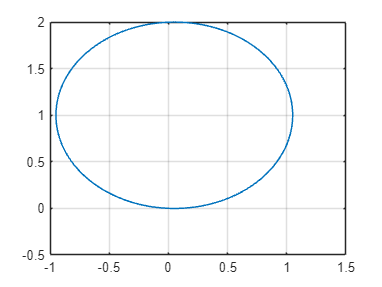

plot(estado(1,:),estado(2,:));
grid on

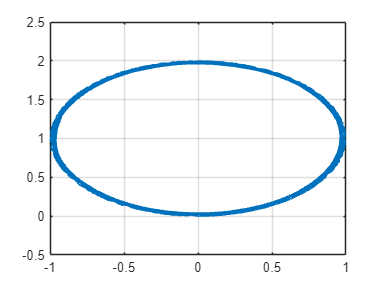

plot(q(:,1),q(:,2));
grid on

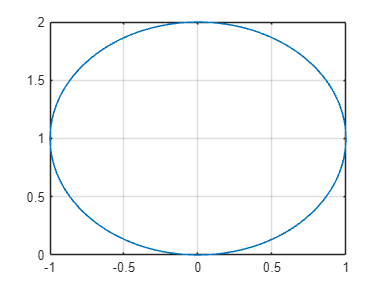

plot(state(1,:),state(2,:));
grid on

### Función RungeKutta

function rk4 = rungeKutta(f,x,u,Ts)
% Create a numeric integrator of type 4-th order Runge-Kutta. Euler is
% faster but work weel only with very low sampling times Ts
    k1              = f(x, u);
    k2              = f(x + Ts / 2 * k1, u);
    k3              = f(x + Ts / 2 * k2, u);
    k4              = f(x + Ts * k3, u);
    rk4             = x + Ts / 6 * (k1 + 2 * k2 + 2 * k3 + k4);
end

function x = simulation(F,x0,ctrl,numberOfIterations)
    x       = x0;         % my vector of states
    for i=1:numberOfIterations
        x_next   = F(x(:,end),ctrl(:,i));
        x       = [x, full(x_next)];     % convert casadi data type to double (matlab data type). and store the sequences of states
    end
end

function dqdt = model(t,X,U)
    w = U(1);
    v = U(2);
    theta = X(3);
    xDot = v*cos(theta);
    yDot = v*sin(theta);
    thetaDot = w;
    dqdt = [xDot; yDot; thetaDot];
end

